
N_moments = 101;
N_point = 101;
a = -0.3; b = 0.3;
x = linspace(a, b, N_point);
delta_approx = zeros(1,length(x));
for ii = 1: N_point
    delta_approx(ii) = (1 + 2 * cos((1:N_moments-1) * pi/2) * chebyshevT((1:N_moments-1)', x(ii)) )./(pi * sqrt(1-x(ii)^2));
end




Kernel_Jackson = KPM_Kernel(N_moments, 'Jackson');
% Kernel_Jackson = ((N_moments+1-(0:N_moments-1)).*cos(pi * (0:N_moments-1)/(N_moments+1)) + ...
                   % sin(pi * (0:N_moments-1)/(N_moments+1))*cot(pi/(N_moments+1)) )/(N_moments + 1);
delta_jackson = zeros(1,length(x));
for ii = 1: N_point
    delta_jackson(ii) = (([1, 2 * cos((1:N_moments-1) * pi/2)] .* Kernel_Jackson) * chebyshevT((0:N_moments-1)', x(ii)) )./(pi * sqrt(1-x(ii)^2));
end


lambda = 3;
Kernel_Lorentz = KPM_Kernel(N_moments, 'Lorentz', lambda);
% Kernel_Lorentz = sinh(lambda*(1-(0:N_moments-1)/N_moments))/sinh(lambda);
delta_Lorentz = zeros(1,length(x));
for ii = 1: N_point
    delta_Lorentz(ii) = (([1, 2 * cos((1:N_moments-1) * pi/2)] .* Kernel_Lorentz) * chebyshevT((0:N_moments-1)', x(ii)) )./(pi * sqrt(1-x(ii)^2));
end


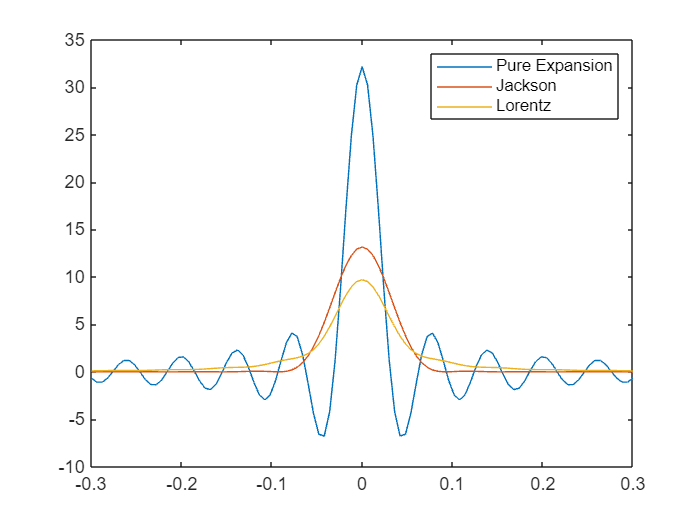


plot(x, delta_approx, x, delta_jackson, x, delta_Lorentz)
legend('Pure Expansion','Jackson','Lorentz')

% exportgraphics(gcf,"KPM_Gibbs.pdf",'BackgroundColor','none','ContentType','vector')

([1, 2 * cos((1:N_moments-1) * pi/2)] .* Kernel_Jackson)